# show case the standard routine for pathology image analysis

## Step-0 Initializing parameters/adding dependencies

addpath(genpath('.\veta_watershed\'));
addpath(genpath([pwd '/FeatureExtraction']));


## Step-1 read the image and do normalization (note that sometimes the normalization may make the image quality worse!)

A good normaliztion method is here: https://github.com/FarhadZanjani/Histopathology-Stain-Color-Normalization

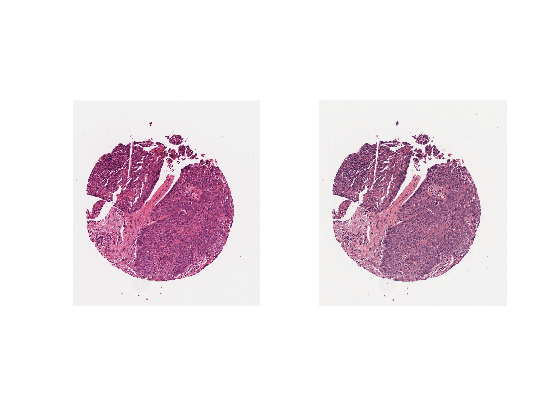

I=imread('OP02_A.tif'); imshow(I)
[I_norm, ~, ~] = normalizeStaining(I);
figure; subplot(1,2,1);imshow(I);
subplot(1,2,2);imshow(I_norm);

I_normRed=I_norm(:,:,1);%show(I_normRed);show(I_norm(:,:,3));

## Step-2 nuclear segmentation

You can use pre-trained DL model or other model for nuclear segmantion, here I use the Veta multiresolution nuclear segmentation.  

Begin nuclei segmentation using multi resolution watershed
Processing at scale 8 pixels.
Processing at scale 10 pixels.
Processing at scale 12 pixels.
Processing at scale 14 pixels.
Merging contours.
 - Allocate memory for calculating distance matrix.
 - Calculating distance matrix.
Elapsed time is 7.979267 seconds.
 - Resolving concurrence.


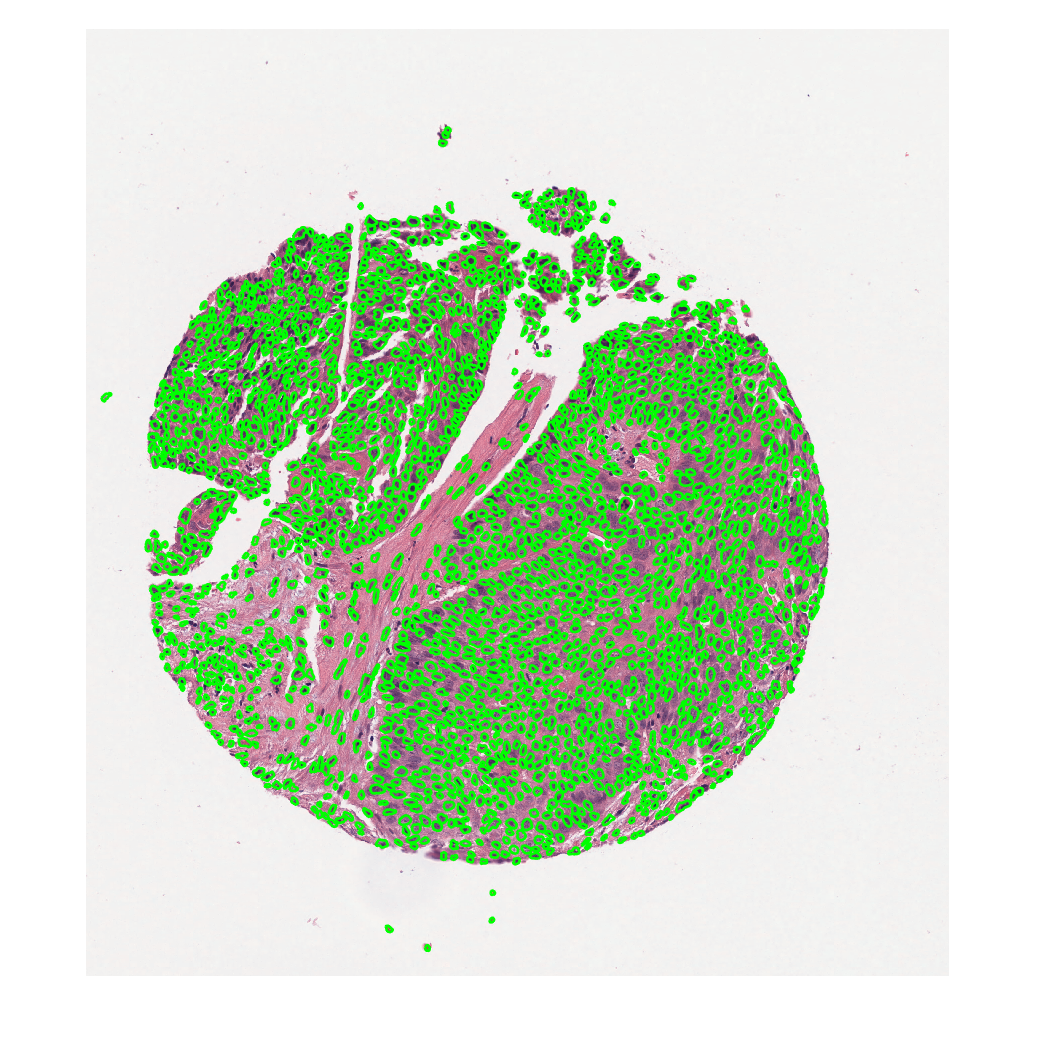

scales = 8:2:14; % for 40X magnification
[bounds, nuclei, properties] = Veta(I_norm, scales);

check nuclear segmentation result here

figure;
imshow(I_norm);hold on;

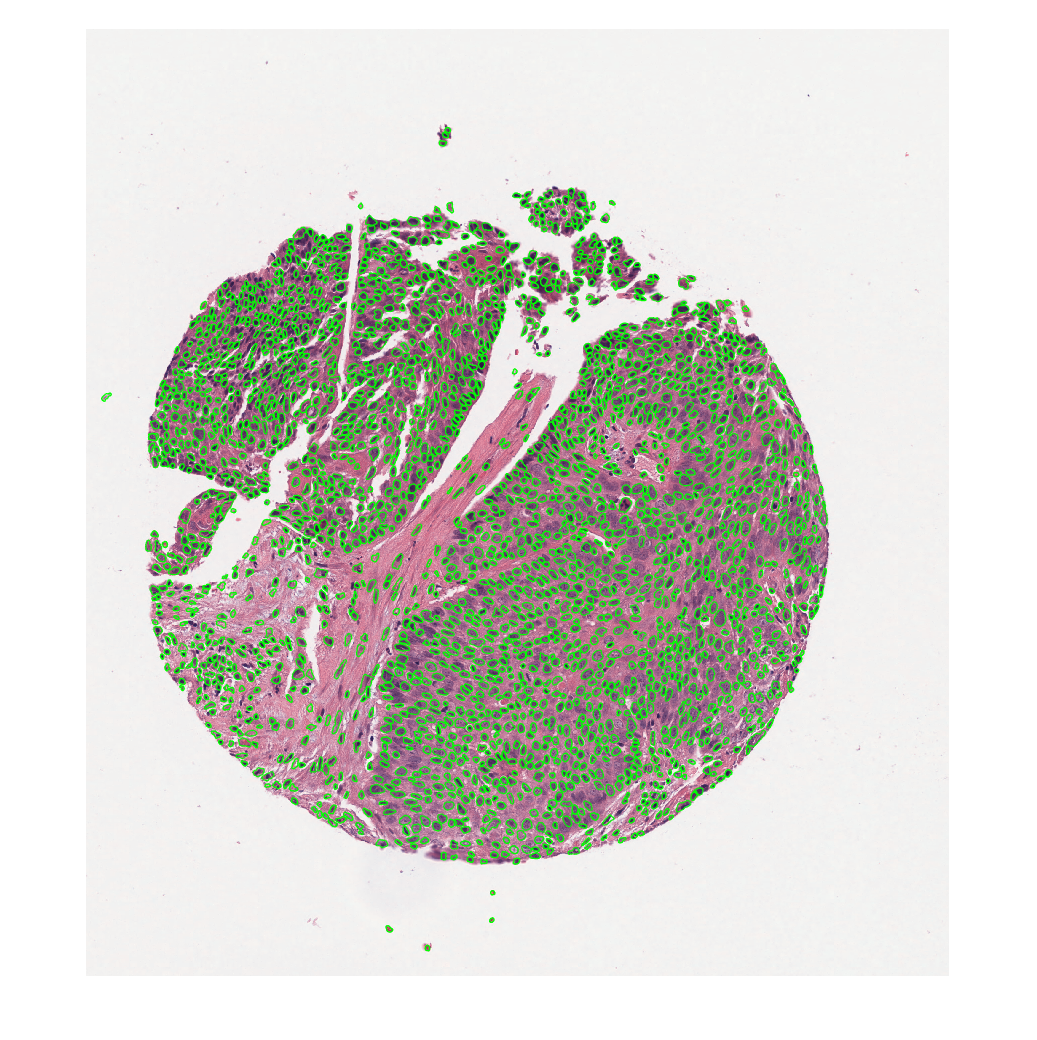

for k = 1:length(nuclei)
        plot(nuclei{k}(:,2), nuclei{k}(:,1), 'g-', 'LineWidth', 1);
end
hold off;            %%% remove the false positive region

## Step-3 morphology feature extraction

note that 1-6 are traditional used nuclear morphology features

img=I;

% 1. graph features(51)
[graphfeats] = extract_all_features(bounds,img,1);


Extracting Graph Features...Elapsed time is 5.459142 seconds.



Extracting Morph Features...

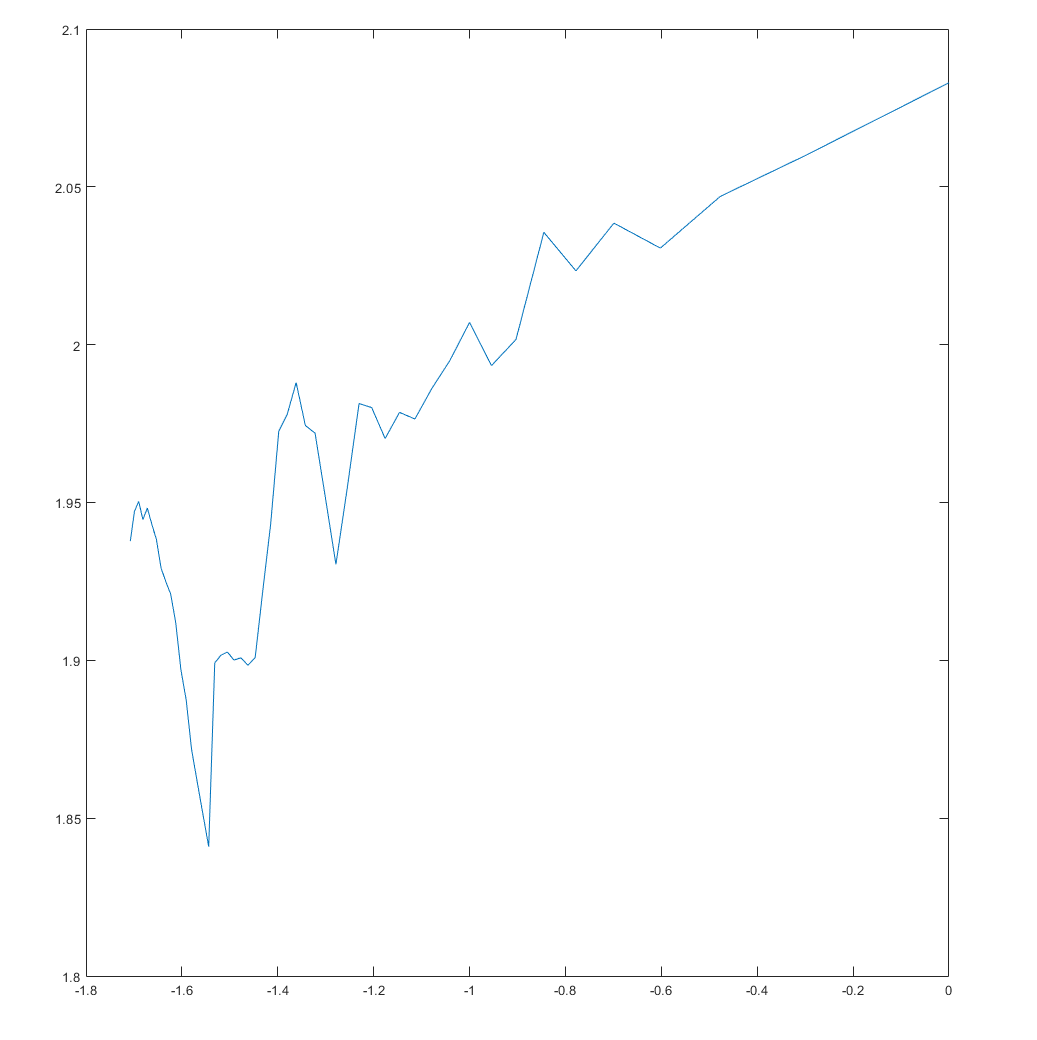

Elapsed time is 23.246217 seconds.



% 2. morphological features(100)
[morphfeats] = extract_all_features(bounds, img, 2);


% 3. CGT features(39) this is the nucear polarity feature
[CGTfeats] = extract_all_features(bounds, img, 3);


Extracting CGT Features...

Error using princomp (line 13)
princomp has been removed. Use pca instead.

Error in fitEllipseToBoundary (line 19)
        components = princomp([bounds(i).r; bounds(i).c]');

Error in 


% 4. cluster graph features(26)
[clustergraphfeats] = extract_all_features(bounds, img, 4);

% 5. haralick features(26)
[haralickfeats] = extract_all_features(bounds, img, 5);

% 6. texture features (720) (Grayscale(15), Gabor(24), Laws(25), Local Binary Pattern(16) = 80 * (HSV 3channels) * (mean, std, mode))
[texturefeats] = extract_texture_features(img);

